# Assignment 02 - A.A. 2023/24

close all
clear
clc


## 0) Variables

M1 = 5;     % [kg]
M2 = 4;     % [kg]
M3 = 5;     % [kg]

J2 = 7;     % [kg*m^2]
J3 = 6;     % [kg*m^2]

M4 = 2;     % [kg]
R = 0.8;    % [m]
r = 0.6;    % [m]

k1 = 300;   % [N/m]
k2 = 350;   % [N/m]
k3 = 50;    % [N/m]

c1 = 0.5;   % [N*s/m]
c2 = 2;     % [N*s/m]
c3 = 10;    % [N*s/m]

## 1.A) Equation of Motion and system matrices

syms x_1(t) theta_2(t) theta_3(t) F(t)

% Kinetic energy -> mass
M_phisic = diag([M1, M2, J2, M3, J3, M4]);
JacM = [1,0,0;  1,0,0   ;  0,1,0    ;
        1,0,-r  ;   0,0,1   ;   -1,0,r];
M_star = JacM.' * M_phisic * JacM;


% Elastic potential energy -> stiffness
k_phisic = diag([k1,k2,k3]);
Jack = [1,0,0;0,-R,-2*r;-1,0,r];
K_star = Jack.' * k_phisic * Jack;

% Dissipative energy -> damping
c_phisic = diag([c1,c2,c3]);
Jacc = Jack;
C_star = Jacc.' * c_phisic * Jacc;

% Lagrangian
Q = [F; 0; -r*F];

% Equations of Motion
syms x_1(t) theta_2(t) theta_3(t) F(t)

x = [x_1; theta_2; theta_3];    % independent variables
dx = diff(x,t,1);               % 1st derivative
ddx = diff(x,t,2);              % 2nd derivative

EoM = M_star*ddx + C_star*dx + K_star*x;
ODESdamped = M_star*ddx + C_star*dx + K_star*x == Q;
ODESundamped = M_star*ddx + K_star*x == Q;

## 1.B) Undamped

[V,D] = eig(-M_star\K_star);            % Eigenvectors and eigenvalues
w_nat = sort(imag(sqrt(diag(D))));      % Natural frequencies

mode_shapes = V ./ V(1, :);         % Normalization to the first row
mode_shapes = [mode_shapes(:, 3), mode_shapes(:, 2), mode_shapes(:, 1)];    % Sorting for increasing w_nat

mode_shapes_1 = mode_shapes(1, :);      % Coefficients for x_1
mode_shapes_2 = mode_shapes(2, :);      % Coefficients for theta_2
mode_shapes_3 = mode_shapes(3, :);      % Coefficients for theta_3

## 1.B) Damped

% State matrix A
B = [M_star, zeros(size(M_star)); zeros(size(M_star)), M_star];
D = [C_star, K_star; -M_star, zeros(size(M_star))];
A = (-B\D);

[V_damp, D_damp] = eig(A);          % Eigenvectors and eigenvalues
lambda = sort(diag(D_damp));        % Lambda solutions
lambda = lambda(2 : 2 : end);       % Selecting one of the conjugate solutions
alpha = -real(lambda);          % Decaying factors
w_damp = imag(lambda);          % Damped frequencies

mode_shapes_damp = V_damp(4:6, :);  % Modes of x (and not x_dot)
mode_shapes_damp = mode_shapes_damp ./ mode_shapes_damp(1, :);      % Normalization to the first row
mode_shapes_damp = [mode_shapes_damp(:, 5), mode_shapes_damp(:, 3), mode_shapes_damp(:, 1)];    % Sorting and selecting

mode_shapes_damp_1 = mode_shapes_damp(1, :);    % Coefficients for x_1
mode_shapes_damp_2 = mode_shapes_damp(2, :);    % Coefficients for theta_2
mode_shapes_damp_3 = mode_shapes_damp(3, :);    % Coefficients for theta_3

h = alpha ./ w_nat;

## 1.C) Rayleigh damping

% Rayleigh components
ray = [1./(2.* w_nat), w_nat./2]\h;

% Rayleigh damping
C_ray = ray(1) * M_star + ray(2) * K_star;

% Updating eigenvalues and eigenvectors
B = [M_star, zeros(size(M_star)); zeros(size(M_star)), M_star];
D = [C_ray, K_star; -M_star, zeros(size(M_star))];
A = (-B\D);

[V_damp, D_damp] = eig(A);          % Eigenvectors and eigenvalues
lambda = sort(diag(D_damp));        % Lambda solutions
lambda = lambda(2 : 2 : end);       % Selecting one of the conjugate solutions
alpha = -real(lambda);          % Decaying factors
w_damp = imag(lambda);          % Damped frequencies

mode_shapes_damp = V_damp(4:6, :);  % Modes of x (and not x_dot)
mode_shapes_damp = mode_shapes_damp ./ mode_shapes_damp(1, :);      % Normalization to the first row
mode_shapes_damp = [mode_shapes_damp(:, 5), mode_shapes_damp(:, 3), mode_shapes_damp(:, 1)];    % Sorting and selecting

mode_shapes_damp_1 = mode_shapes_damp(1, :);    % Coefficients for x_1
mode_shapes_damp_2 = mode_shapes_damp(2, :);    % Coefficients for theta_2
mode_shapes_damp_3 = mode_shapes_damp(3, :);    % Coefficients for theta_3

h = alpha ./ w_nat;

## 2.A) Free motion responses

% Initial conditions
x_1_0 = 0.1;            %[m]
theta_2_0 = pi/12;      %[rad]
theta_3_0 = -pi/12;     %[rad]
v_1_0 = 1;              %[m/s]
w_2_0 = 0.5;            %[rad/s]
w_3_0 = 2;              %[rad/s]

% System
syms C_1 C_2 C_3 Phi_1 Phi_2 Phi_3
C_i = [C_1; C_2; C_3];
Phi_i = [Phi_1; Phi_2; Phi_3];

% Position I.C. equations
eq_cond_x_1     = sum((C_i .* abs(mode_shapes_damp_1).') .* cos(Phi_i + angle(mode_shapes_damp_1).')) == x_1_0;
eq_cond_theta_2 = sum((C_i .* abs(mode_shapes_damp_2).') .* cos(Phi_i + angle(mode_shapes_damp_2).')) == theta_2_0;
eq_cond_theta_3 = sum((C_i .* abs(mode_shapes_damp_3).') .* cos(Phi_i + angle(mode_shapes_damp_3).')) == theta_3_0;

shift = atan (w_damp ./ alpha);   % don't know why

% Velocity I.C. equations
eq_cond_v_1 = sum((C_i .* abs(mode_shapes_damp_1).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - v_1_0;
eq_cond_w_2 = sum((C_i .* abs(mode_shapes_damp_2).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - w_2_0;
eq_cond_w_3 = sum((C_i .* abs(mode_shapes_damp_3).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - w_3_0;

% Solving
eq_bundle = [eq_cond_x_1, eq_cond_theta_2, eq_cond_theta_3, eq_cond_v_1, eq_cond_w_2, eq_cond_w_3];
solution = vpasolve(eq_bundle, [C_1, C_2, C_3, Phi_1, Phi_2, Phi_3]);

% Unknowns
const = [double(solution.C_1), double(solution.C_2), double(solution.C_3)];
phase = [double(solution.Phi_1), double(solution.Phi_2), double(solution.Phi_3)];

% Matrix of amplitude frequency components -> CHECK
abs([const(1)*mode_shapes_damp(:, 1), const(2)*mode_shapes_damp(:, 2), const(3)*mode_shapes_damp(:, 3)])

ans =     0.0870    0.1981    0.9423
    1.6566    0.0465    2.0623
    1.0822    0.0096    3.0362


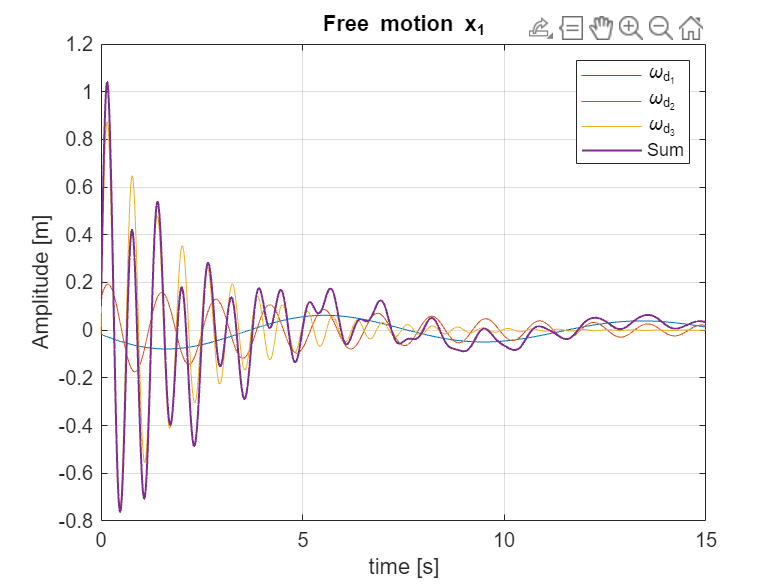


% Plot variables
alfa = alpha.';
omega_d = w_damp.';
%phase = wrapTo2Pi(phase)
t = linspace(0, 70, 70*1e4);

% Plot x_1
x_1 = 0;

% Coefficient for x_1
amplitude = abs(mode_shapes_damp_1);
shift = angle(mode_shapes_damp_1);

figure()

for i = 1:3
    x_1 = x_1 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, x_1, LineWidth = 1)
titleStr = "Free motion x_1";
title(titleStr);
grid on;
ylabel("Amplitude [m]");
xlabel("time [s]");
xlim([0, 15]);
legend("\omega_{d_1}", "\omega_{d_2}", "\omega_{d_3}", "Sum");

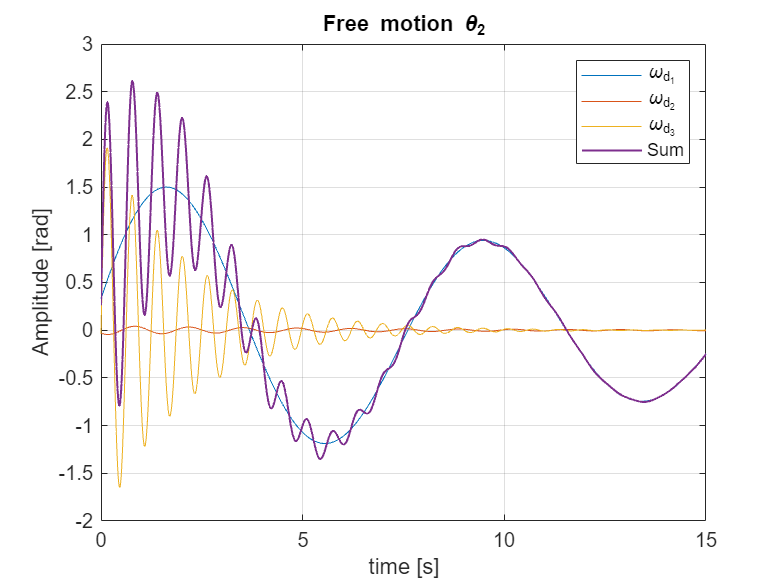


% Plot theta_2
theta_2 = 0;

% Coefficient for theta_2
amplitude = abs(mode_shapes_damp_2);
shift = angle(mode_shapes_damp_2);

figure()

for i = 1:3
    theta_2 = theta_2 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, theta_2, LineWidth = 1)
titleStr = "Free motion \theta_2";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("time [s]");
xlim([0, 15]);
legend("\omega_{d_1}", "\omega_{d_2}", "\omega_{d_3}", "Sum");

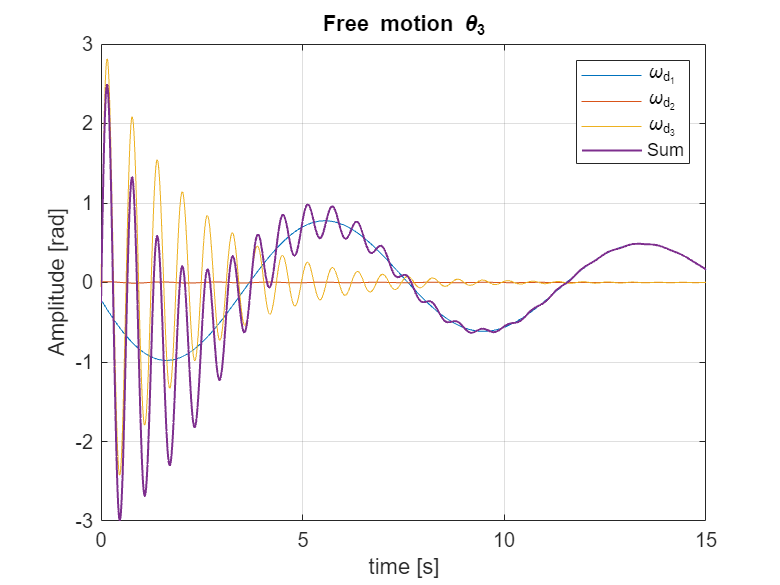


% Plot theta_3
theta_3 = 0;

% Coefficient for theta_3
amplitude = abs(mode_shapes_damp_3);
shift = angle(mode_shapes_damp_3);

figure()

for i = 1:3
    theta_3 = theta_3 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, theta_3, LineWidth = 1)
titleStr = "Free motion \theta_3";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("time [s]");
xlim([0, 15]);
legend("\omega_{d_1}", "\omega_{d_2}", "\omega_{d_3}", "Sum");

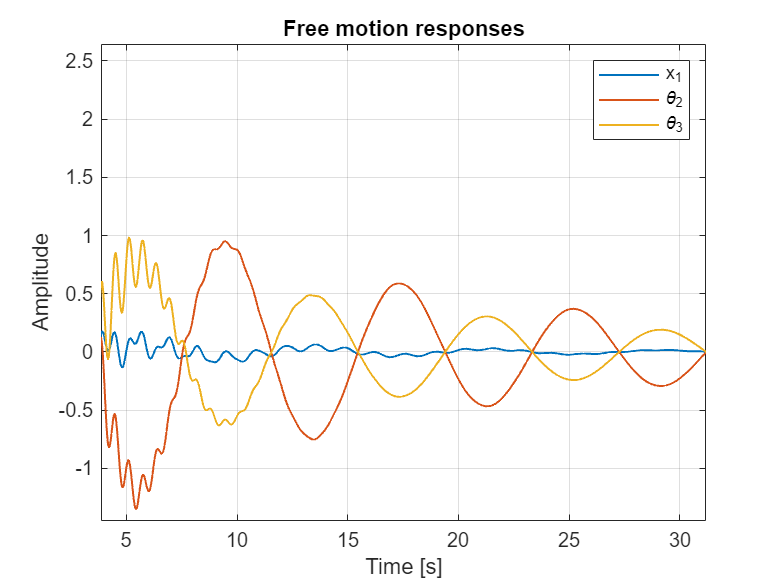


% Plotting together
figure()
plot(t, x_1, LineWidth = 1)
hold on;
plot(t, theta_2, LineWidth = 1)
plot(t, theta_3, LineWidth = 1)
grid on;
titleStr = "Free motion responses";
title(titleStr);
ylabel("Amplitude");
xlabel("Time [s]");
xlim([0, 40]);
legend("x_1", "\theta_2", "\theta_3");

## 2.B) Imposing I.C. - mode 1

% Imposing initial conditions -> I.C equal to eigenvector values of w_d_1
x_1_0 = mode_shapes_damp(1, 1);         %[m]
theta_2_0 = mode_shapes_damp(2, 1);     %[rad]
theta_3_0 = mode_shapes_damp(3, 1);     %[rad]
v_1_0 = 0;              %[m/s]
w_2_0 = 0;              %[rad/s]
w_3_0 = 0;              %[rad/s]

% System
syms C_1 C_2 C_3 Phi_1 Phi_2 Phi_3
C_i = [C_1; C_2; C_3];
Phi_i = [Phi_1; Phi_2; Phi_3];

% Position I.C. equations
eq_cond_x_1     = sum((C_i .* abs(mode_shapes_damp_1).') .* cos(Phi_i + angle(mode_shapes_damp_1).')) == x_1_0;
eq_cond_theta_2 = sum((C_i .* abs(mode_shapes_damp_2).') .* cos(Phi_i + angle(mode_shapes_damp_2).')) == theta_2_0;
eq_cond_theta_3 = sum((C_i .* abs(mode_shapes_damp_3).') .* cos(Phi_i + angle(mode_shapes_damp_3).')) == theta_3_0;

shift = atan (w_damp ./ alpha);   % don't know why

% Velocity I.C. equations
eq_cond_v_1 = sum((C_i .* abs(mode_shapes_damp_1).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - v_1_0;
eq_cond_w_2 = sum((C_i .* abs(mode_shapes_damp_2).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - w_2_0;
eq_cond_w_3 = sum((C_i .* abs(mode_shapes_damp_3).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - w_3_0;

% Solving
eq_bundle = [eq_cond_x_1, eq_cond_theta_2, eq_cond_theta_3, eq_cond_v_1, eq_cond_w_2, eq_cond_w_3];
solution = vpasolve(eq_bundle, [C_1, C_2, C_3, Phi_1, Phi_2, Phi_3]);

% Unknowns
%const = [double(solution.C_1), double(solution.C_2), double(solution.C_3)];
const = abs([double(solution.C_1), double(solution.C_2), double(solution.C_3)]);
phase = [double(solution.Phi_1), double(solution.Phi_2), double(solution.Phi_3)];

% Matrix of amplitude frequency components -> CHECK
abs([const(1)*mode_shapes_damp(:, 1), const(2)*mode_shapes_damp(:, 2), const(3)*mode_shapes_damp(:, 3)])

ans =     1.0028    0.0000    0.0000
   19.1004    0.0000    0.0000
   12.4779    0.0000    0.0000


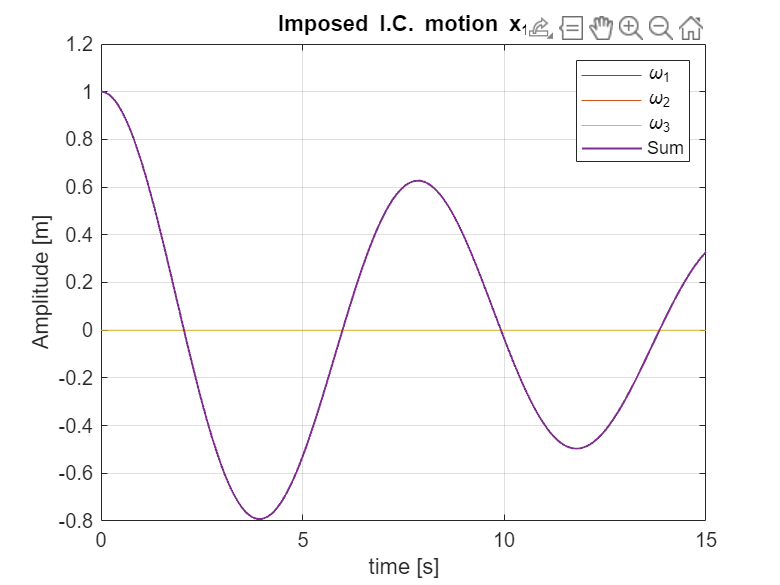


% Plot variables
alfa = alpha.';
omega_d = w_damp.';
%phase = wrapTo2Pi(phase)
t = linspace(0, 70, 70*1e4);

% Plot x_1
x_1 = 0;

% Coefficient for x_1
amplitude = abs(mode_shapes_damp_1);
shift = angle(mode_shapes_damp_1);

figure()

for i = 1:3
    x_1 = x_1 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, x_1, LineWidth = 1)
titleStr = "Imposed I.C. motion x_1";
title(titleStr);
grid on;
ylabel("Amplitude [m]");
xlabel("time [s]");
xlim([0, 15]);
legend("\omega_1", "\omega_2", "\omega_3", "Sum");

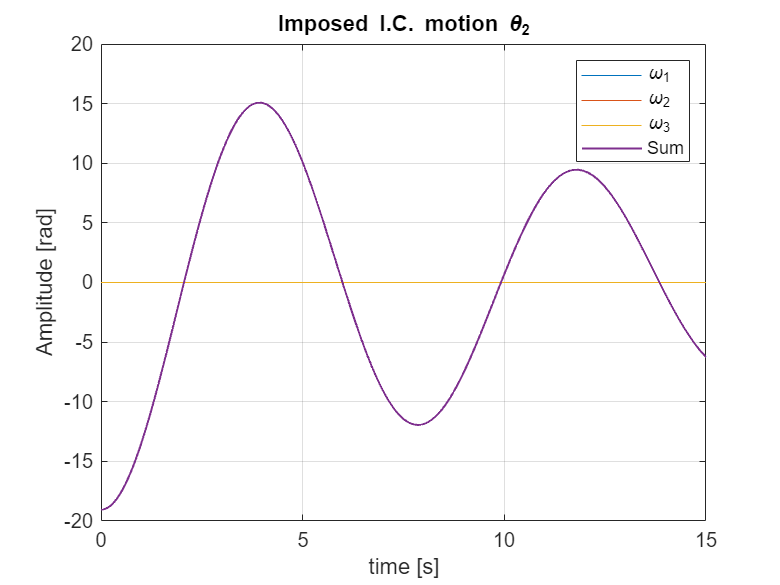


% Plot theta_2
theta_2 = 0;

% Coefficient for theta_2
amplitude = abs(mode_shapes_damp_2);
shift = angle(mode_shapes_damp_2);

figure()

for i = 1:3
    theta_2 = theta_2 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, theta_2, LineWidth = 1)
titleStr = "Imposed I.C. motion \theta_2";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("time [s]");
xlim([0, 15]);
legend("\omega_1", "\omega_2", "\omega_3", "Sum");

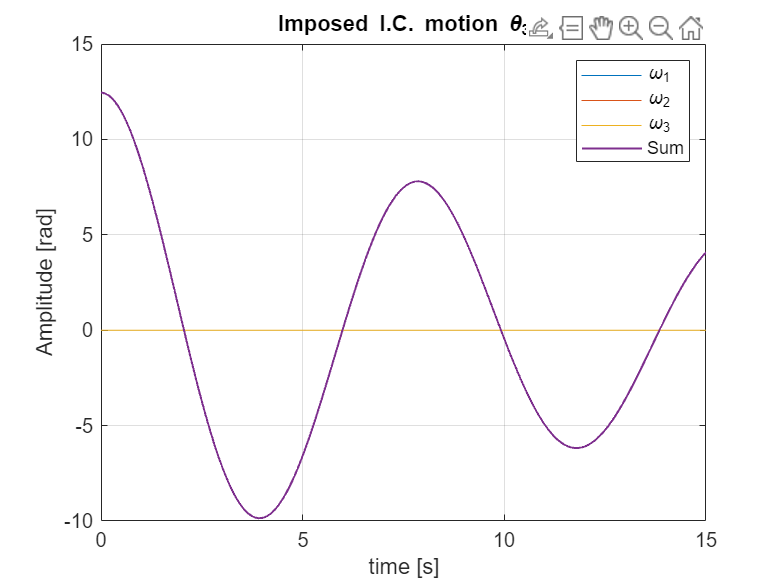


% Plot theta_3
theta_3 = 0;

% Coefficient for theta_3
amplitude = abs(mode_shapes_damp_3);
shift = angle(mode_shapes_damp_3);

figure()

for i = 1:3
    theta_3 = theta_3 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, theta_3, LineWidth = 1)
titleStr = "Imposed I.C. motion \theta_3";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("time [s]");
xlim([0, 15]);
legend("\omega_1", "\omega_2", "\omega_3", "Sum");

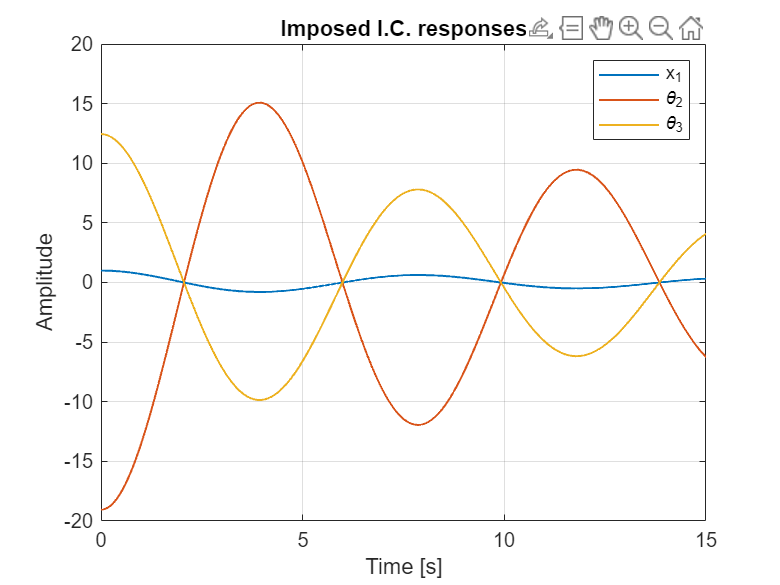


% Plotting together
figure()
plot(t, x_1, LineWidth = 1)
hold on;
plot(t, theta_2, LineWidth = 1)
plot(t, theta_3, LineWidth = 1)
grid on;
titleStr = "Imposed I.C. responses";
title(titleStr);
ylabel("Amplitude");
xlabel("Time [s]");
xlim([0, 15]);
legend("x_1", "\theta_2", "\theta_3");

## 3.A) Frequency response matrix